## A. Conventional Flow Compensated Slice-Select Gradient

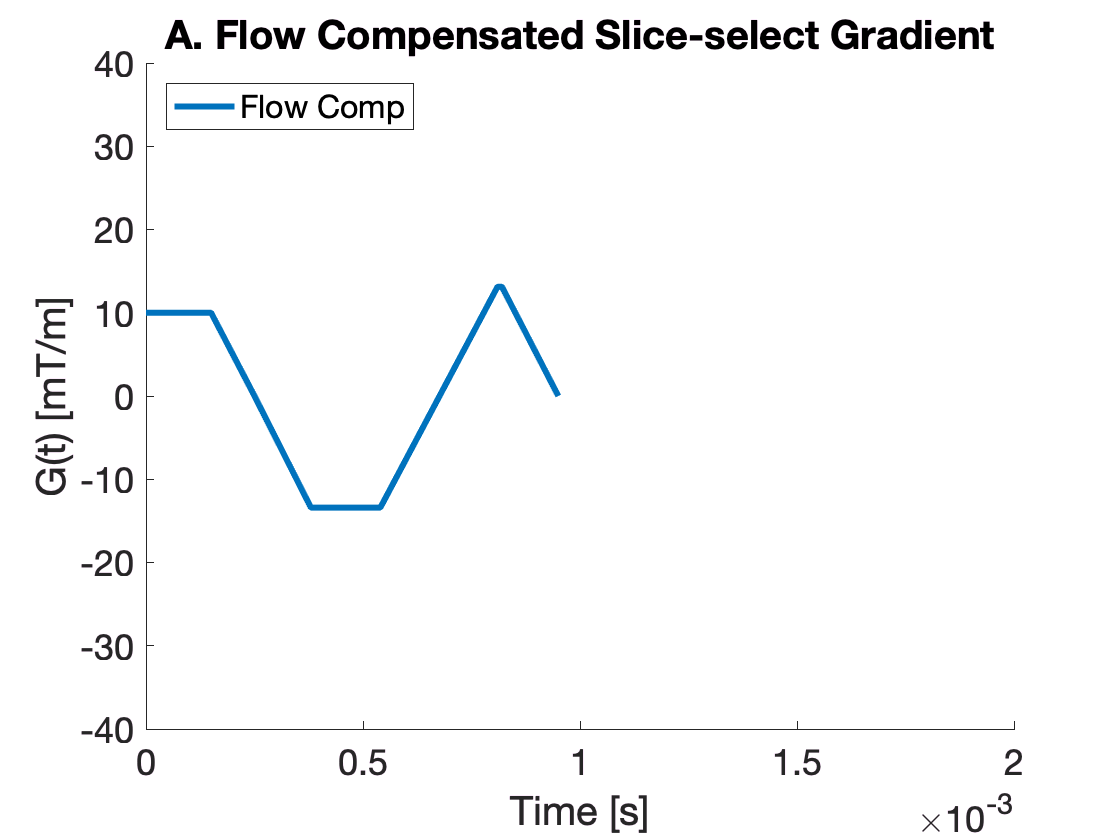

clear params;
params.gmax = 50;       % Maximum gradient amplitude, mT/m
params.smax = 100;      % Maximum slew rate, T/m/s
params.dt = 10e-6;      % Gradient raster time, s
params.g_ss = 10;       % Slice select gradient amplitude, mT/m
params.p_ss = 0.15;     % Slice select gradient plateau, ms

[G_FC, M0S, M1S, t_ss, G_ss] = conventional_flowcomp(params);

t_FC = (0:params.dt:(length(G_FC)-1)*params.dt);

set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',18);
figure; hold on;
  plot(t_FC,G_FC); axis([0 2e-3 -40 40]);
  title('A. Flow Compensated Slice-select Gradient');
  xlabel('Time [s]'); ylabel('G(t) [mT/m]'); legend('Flow Comp','Location','NorthWest')

## B. Conventional Flow Encoded Gradient

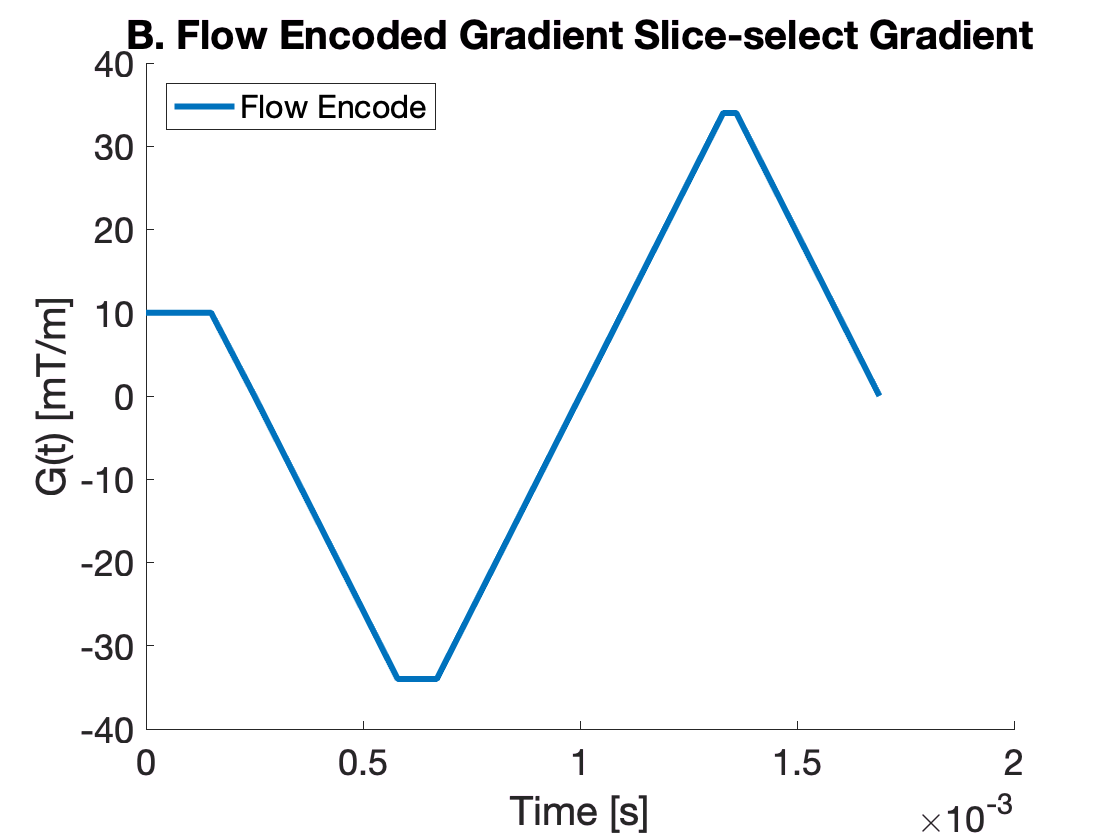

clear params;
params.mode = 'free';
params.gmax = 50;       % Maximum gradient amplitude, mT/m
params.smax = 100;      % Maximum slew rate, T/m/s
params.dt = 10e-6;      % Gradient raster time, s
params.g_ss = 10;       % Slice select gradient amplitude, mT/m
params.p_ss = 0.15;     % Slice select gradient plateau, ms

params.VENC = 1.5e-3;   % Velocity ENCoding strength m/ms
params.M0S = M0S;       % Slice select M0 (from above)    
params.M1S = M1S;       % Slice select M1 (from above)
params.G_ss = G_ss;     % Slice select gradient (from above)

[G_FE, ~] = conventional_flowencode(params);
t_FE= (0:params.dt:(length(G_FE)-1)*params.dt);

set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',18);
figure; hold on;
  plot(t_FE,G_FE); axis([0 2e-3 -40 40]);
  title('B. Flow Encoded Gradient Slice-select Gradient');
  xlabel('Time [s]'); ylabel('G(t) [mT/m]'); legend('Flow Encode','Location','NorthWest')

## C. Conventional Flow Compensated/Encoded Gradients

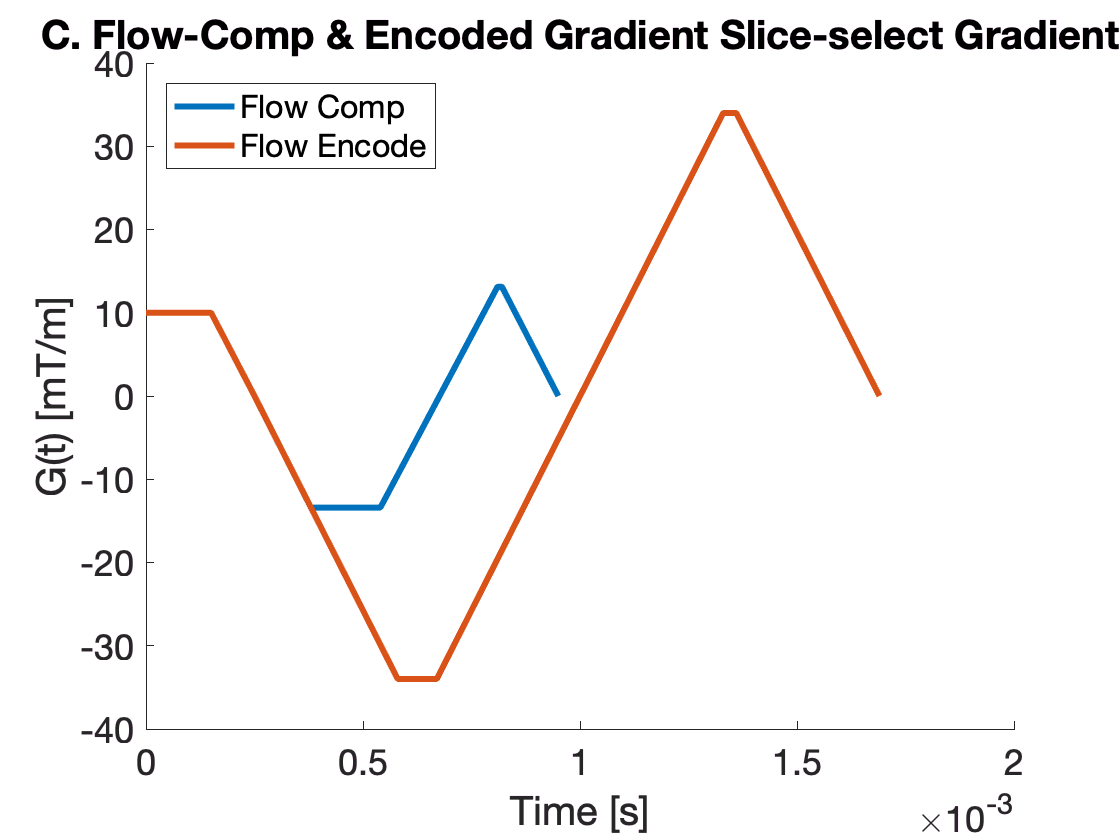

clear params;
params.mode = 'free';
params.gmax = 50;       % Maximum gradient amplitude, mT/m
params.smax = 100;      % Maximum slew rate, T/m/s
params.dt = 10e-6;      % Gradient raster time, s
params.g_ss = 10;       % Slice select gradient amplitude, mT/m
params.p_ss = 0.15;     % Slice select gradient plateau, ms

[G_FC, M0S, M1S, t_ss, G_ss] = conventional_flowcomp(params);

params.VENC = 1.5e-3;   % Velocity ENCoding strength m/ms
params.M0S = M0S;       % Slice select M0 (from above)    
params.M1S = M1S;       % Slice select M1 (from above)
params.G_ss = G_ss;     % Slice select gradient (from above)

[G_FE, ~] = conventional_flowencode(params);

t_FC = (0:params.dt:(length(G_FC)-1)*params.dt);
t_FE = (0:params.dt:(length(G_FE)-1)*params.dt);

set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',18);
figure; hold on;
  plot(t_FC,G_FC); plot(t_FE,G_FE);  axis([0 2e-3 -40 40]);
  title('C. Flow-Comp & Encoded Gradient Slice-select Gradient');
  xlabel('Time [s]'); ylabel('G(t) [mT/m]'); legend('Flow Comp','Flow Encode','Location','NorthWest')

## D. Conventional Bipolar Flow Encoding Gradients

clear params;
params.mode = 'free';
params.gmax = 50*1e-3;  % Maximum gradient amplitude, T/m
params.smax = 100;      % Maximum slew rate, T/m/s
params.dt = 10e-6;      % Gradient raster time, s
params.VENC = 1.5e-3;   % Velocity ENCoding strength m/ms

GAM = 2*pi*42.57;       % 1/(s*T)
DeltaM1 = pi/(GAM*params.VENC);  % mT/m x ms^2

params.moment_params = [];
params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, -M0S(1,end), 1.0e-3];             % Target M0
params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, -M1S(1,end)+DeltaM1/2, 1.0e-3];   % Target M1

[G_FE, ~] = get_min_TE_free(params, 5.0);

Testing TE = 2.500 1.250 0.625 0.938 1.094 1.172 1.211 1.230 1.221 1.216 1.213 Final TE = 1.216 ms


FE_pos = horzcat(G_ss,G_FE).*1000;

params.moment_params = [];
params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, -M0S(1,end), 1.0e-3];             % Target M0
params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, -M1S(1,end)-DeltaM1/2, 1.0e-3];   % Target M1

[G_FE, ~] = get_min_TE_free(params, 5.0);

Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 0.977 0.957 0.947 0.952 0.955 Final TE = 0.957 ms


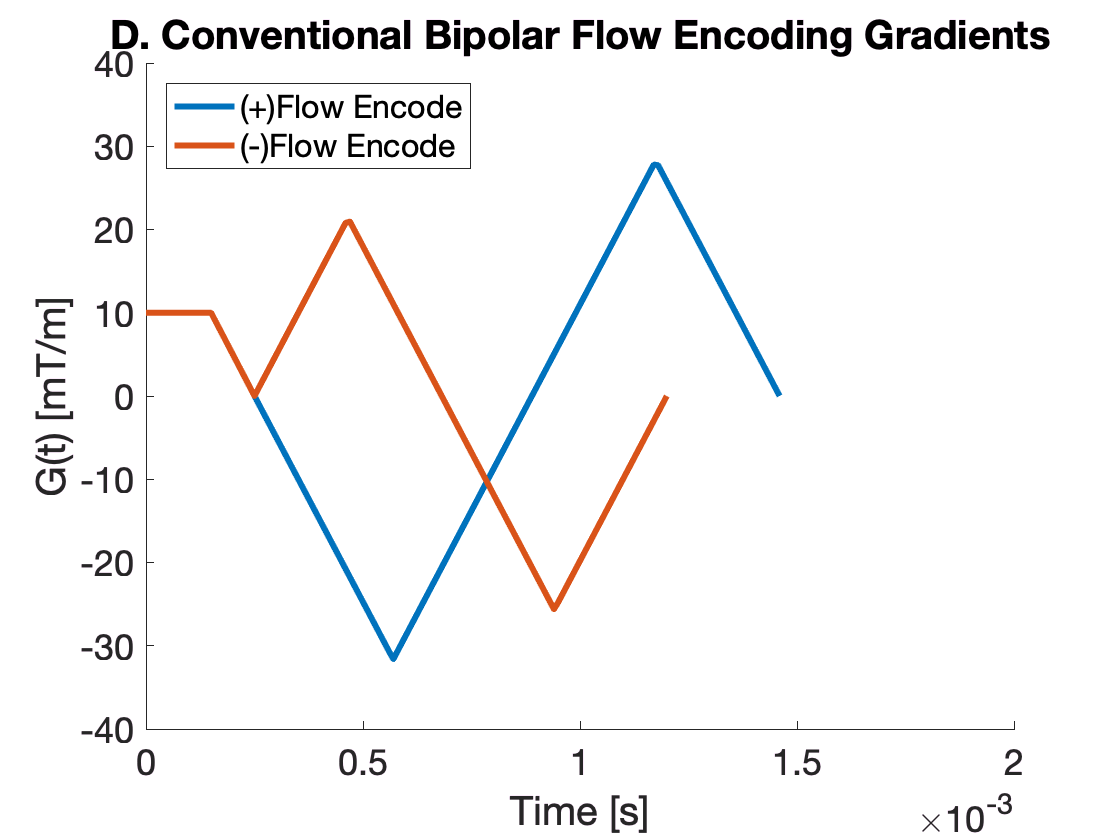

FE_neg = horzcat(G_ss,G_FE).*1000;

tFE_pos = (0:params.dt:(length(FE_pos)-1)*params.dt);
tFE_neg = (0:params.dt:(length(FE_neg)-1)*params.dt);
figure; hold on;
  plot(tFE_pos,FE_pos); plot(tFE_neg,FE_neg);  axis([0 2e-3 -40 40]);
  title('D. Conventional Bipolar Flow Encoding Gradients');
  xlabel('Time [s]'); ylabel('G(t) [mT/m]'); legend('(+)Flow Encode','(-)Flow Encode','Location','NorthWest')

## E. Optimized Asymmetric Flow Encoding Gradients

% This code has a linear (not a bisection) search for the optimal alpha, which is slow ;(
clear params;
params.mode = 'free';
params.gmax = 50*1e-3;  % Maximum gradient amplitude, T/m
params.smax = 100;      % Maximum slew rate, T/m/s
params.dt = 10e-6;      % Gradient raster time, s
params.VENC = 1.5e-3;   % Velocity ENCoding strength m/ms
params.g_ss = 10;       % Slice select gradient amplitude, mT/m
params.p_ss = 0.15;     % Slice select gradient plateau, ms

[G_FC, M0S, M1S, t_ss, G_ss] = conventional_flowcomp(params);

params.VENC = 1.5e-3;   % Velocity ENCoding strength m/ms
params.M0S = M0S;       % Slice select M0 (from above)    
params.M1S = M1S;       % Slice select M1 (from above)
params.G_ss = G_ss;     % Slice select gradient (from above)

% % Create a slice select gradient (without a ramp down, as we will brridge the encoding gradients)
% G_ss = horzcat(linspace(params.g_ss*1e-3,params.g_ss*1e-3,(ceil(params.p_ss*1e-3/params.dt))));
% t_ss = length(G_ss)*params.dt;

t_vec = 0:params.dt:(length(G_ss)-1)*params.dt;    
M0S = cumsum((G_ss.*params.dt).*1e6,2);          % [mT/m x ms]
M1S = cumsum((G_ss.*t_vec*params.dt).*1e9,2);    % [mT/m x ms^2]
GAM = 2*pi*42.57;                % 1/(s*T)
DeltaM1 = pi/(GAM*params.VENC);  % mT/m * ms^2
    
for i = 0:0.025:0.5   % Loop over possible values of alpha

    alpha = i;
    %params.gfix = [params.g_ss/1000, 0];   % This does bridging of SS and FE, but only works in Python
    params.moment_params = [];
    params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, -M0S(1,end), 1.0e-3];                   % Target M0
    params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, -M1S(1,end)+(DeltaM1*alpha), 1.0e-3];   % Target M1
    [G1, T1] = get_min_TE_free(params, 5.0);
    FE_pos = horzcat(G_ss,G1).*1000;
    
    params.moment_params = [];
    params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, -M0S(1,end), 1.0e-3];                       % Target M0
    params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, -M1S(1,end)-(DeltaM1*(1-alpha)), 1.0e-3];   % Target M1
    params.TE = T1;
    [G2, debug] = gropt(params);
    T2 = length(G2)*params.dt*1000;
    FE_neg = horzcat(G_ss,G2).*1000;
    
    if abs(T1-T2) <= 0.01 && debug == 0   % Stop when the waveforms are equal and constraints met 
        break
    end
    
end

Testing TE = 2.500 1.250 0.625 0.312 0.469 0.547 0.586 0.566 0.576 0.571 0.574 Final TE = 0.576 ms


Testing TE = 2.500 1.250 0.625 0.938 0.781 0.703 0.664 0.645 0.654 0.649 0.647 Final TE = 0.647 ms


Testing TE = 2.500 1.250 0.625 0.938 0.781 0.703 0.742 0.723 0.713 0.708 0.706 Final TE = 0.706 ms


Testing TE = 2.500 1.250 0.625 0.938 0.781 0.703 0.742 0.762 0.752 0.757 0.754 Final TE = 0.757 ms


Testing TE = 2.500 1.250 0.625 0.938 0.781 0.859 0.820 0.801 0.791 0.796 0.793 Final TE = 0.796 ms


Testing TE = 2.500 1.250 0.625 0.938 0.781 0.859 0.820 0.840 0.830 0.835 0.837 Final TE = 0.837 ms


Testing TE = 2.500 1.250 0.625 0.938 0.781 0.859 0.898 0.879 0.869 0.864 0.867 Final TE = 0.867 ms


Testing TE = 2.500 1.250 0.625 0.938 0.781 0.859 0.898 0.879 0.889 0.894 0.896 Final TE = 0.896 ms


Testing TE = 2.500 1.250 0.625 0.938 0.781 0.859 0.898 0.918 0.928 0.923 0.925 Final TE = 0.925 ms


Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 0.977 0.957 0.947 0.952 0.955 Final TE = 0.957 ms


Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 0.977 0.957 0.967 0.972 0.974 Final TE = 0.977 ms


Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 0.977 0.996 1.006 1.001 1.003 Final TE = 1.006 ms


Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 1.055 1.035 1.025 1.021 1.023 Final TE = 1.025 ms


Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 1.055 1.035 1.045 1.050 1.047 Final TE = 1.047 ms


Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 1.055 1.074 1.064 1.069 1.067 Final TE = 1.067 ms


Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 1.055 1.074 1.084 1.089 1.086 Final TE = 1.086 ms


Testing TE = 2.500 1.250 0.625 0.938 1.094 1.172 1.133 1.113 1.104 1.108 1.106 Final TE = 1.106 ms


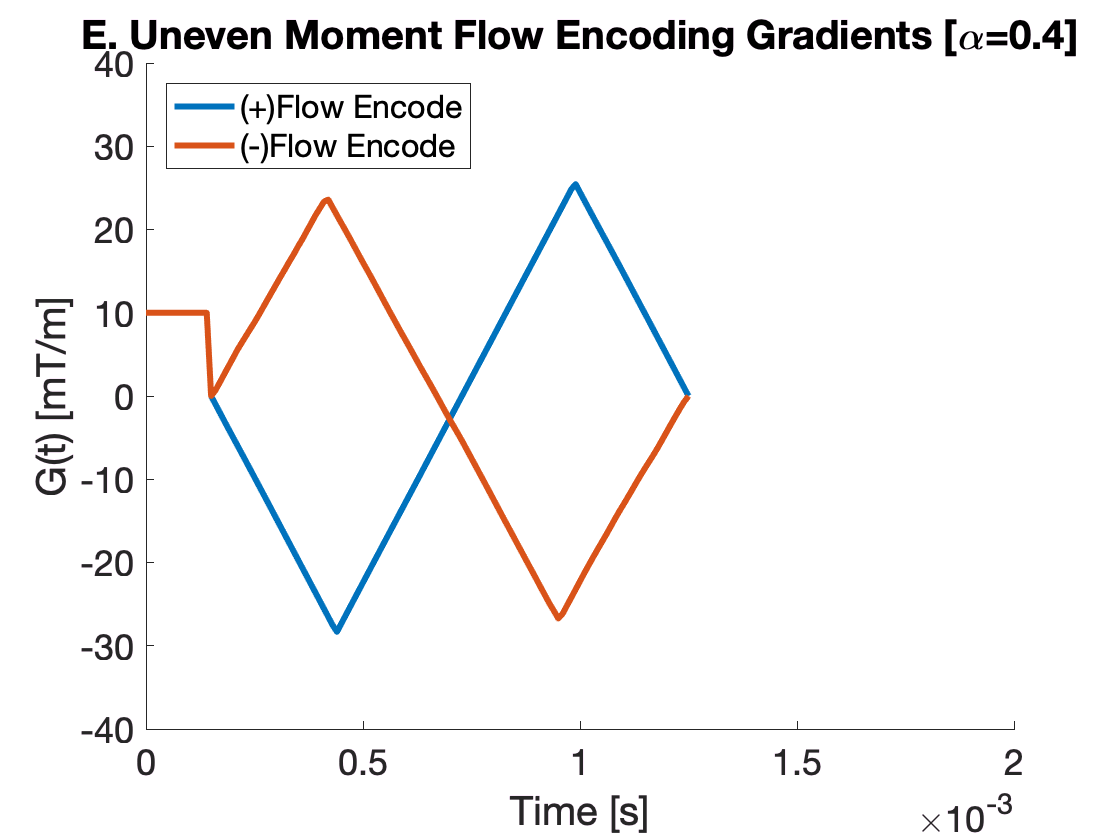

tFE_pos = (0:params.dt:(length(FE_pos)-1)*params.dt);
tFE_neg = (0:params.dt:(length(FE_neg)-1)*params.dt);
figure; hold on;
  title(['E. Uneven Moment Flow Encoding Gradients [\alpha=',num2str(alpha),']']);
  plot(tFE_pos,FE_pos); plot(tFE_neg,FE_neg);  axis([0 2e-3 -40 40]);
  xlabel('Time [s]'); ylabel('G(t) [mT/m]'); legend('(+)Flow Encode','(-)Flow Encode','Location','NorthWest') 